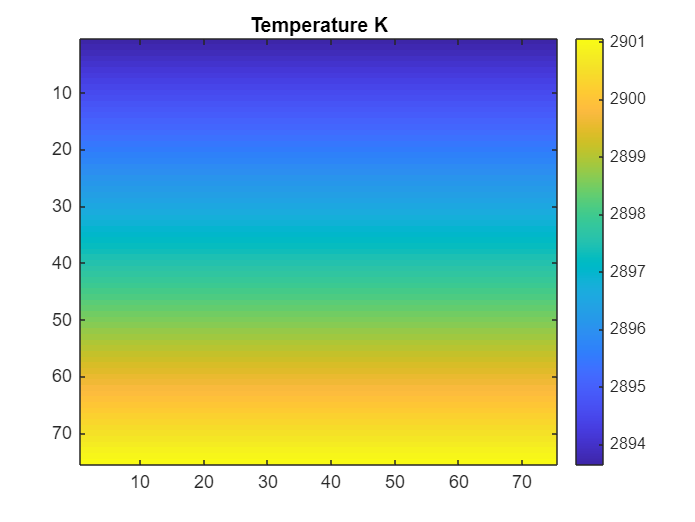

clear
colorPalette = [119,170,221;153,221,255;68,187,153;187,204,51;238,221,136;238,136,102;255,170,187;0,119,187;51,187,238;0,153,136;238,119,51;204,51,17;238,51,119;51,34,136;136,204,238;68,170,153;17,119,51;204,102,119;136,34,85]./256;



tempMat = readmatrix('build/TempGrid.csv');
phaseMat = readmatrix('build/PhaseGrid.csv');
grainMat = readmatrix("build/GrainGrid.csv");
particleMat = readmatrix("build/ParticleGrid.csv");
figure
imagesc(tempMat);
title("Temperature K")
colorbar

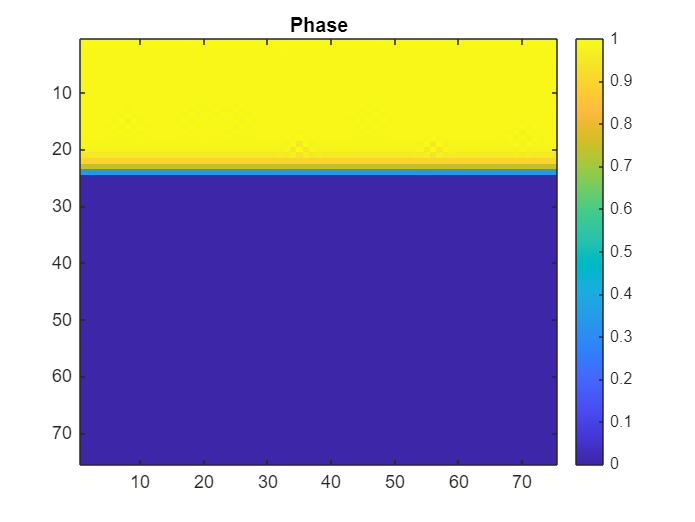

figure
imagesc(phaseMat)
title('Phase')
colorbar
clim([0,1])

figure
[h1,w1] = size(tempMat)

h1 = 75

w1 = 75

numGrains = max(grainMat,[],'all')

numGrains = 33

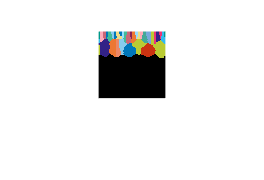

grainR = zeros(h1,w1);
grainG = zeros(h1,w1);
grainB = zeros(h1,w1);
for i = 1:numGrains
        color = colorPalette(randi(length(colorPalette)),:);
        grainMask = grainMat() == i;
        grainR(grainMask)=color(1);
        grainG(grainMask)=color(2);
        grainB(grainMask)=color(3);
end
    imageOut(:,:,1) = grainR;
imageOut(:,:,2) = grainG; 
    imageOut(:,:,3) = grainB;
    imshow(imageOut)

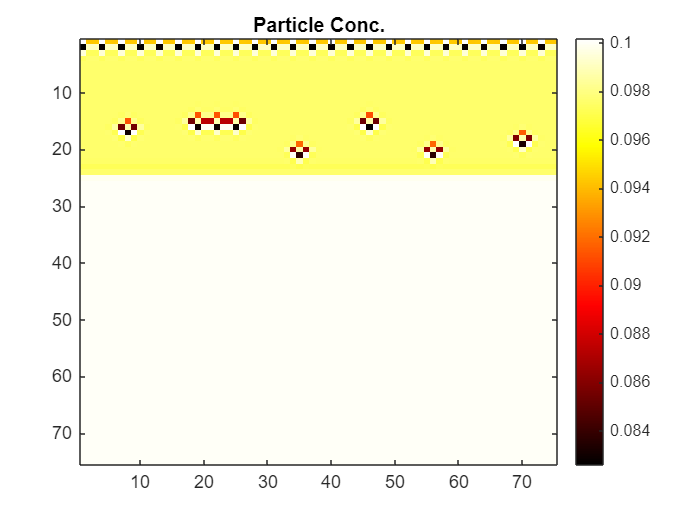


    
figure
imagesc(particleMat)

title('Particle Conc.')
colorbar

colormap hot